addpath('../')

# Milestone 1: Coordinate frame relations

## Coordinate Frames:

N = (O, n1, n2, n3)

B = (H, b1, b2, b3)

H = (O, ir, itheta, ih)

M = (O, m1, m2, m3)

*See Project Assignment for definition of coordinate frames.*

## Derivation of [BN] using (3-1-3) Euler Angles

B frame - (3-1-3) = ($\psi$, $\theta$, $\phi$)

% syms psi theta phi
%     BN = euler2dcm313([psi, theta, phi])

## Derivation of [HN] using (3-1-3) Euler Angles

H-frame - (3-1-3) = ($\Omega$, $i$, $\theta$), $\theta = \omega + \nu$, but $\omega$ is undefined, so $\theta=\nu$ and (3-1-3) = ($\Omega$, $i$, $\nu$).

% syms Omega i nu
% HN = euler2dcm313([0, i, nu])

## Derivation of [MN] using (3-1-3) Euler Angles

M-frame - (3-1-3) = ($\beta_{m_0} + \omega_e t$, $\gamma_m$, 0) = ($\alpha$, $\gamma_m$, 0)

% syms beta_m gamma_mm
% MN = euler2dcm313([beta_m, gamma_mm, 0])

## Derivation of [HM] using (3-1-3) Euler Angles

% HM = HN*MN'
% % Clear the variables
% BN = [];
% HN = [];

# Milestone 2: Numerical Integrator

## RK4 Numerical Integrator

State: **X **= [$\bf\sigma$, $\bf \omega$]$^T$

Dynamics: $[I]\mathbf{\dot\omega}_{B/N}=-\mathbf{\omega}_{B/N} \times [I]\mathbf{\omega}_{B/N} + \mathbf{u}$

RK4 Method:


$$y_{n+1}=y_n + \frac{h}{6}(k_1 + 2k_2 + 2k_3 + k_4)$$



$$t_{n+1} = t_n + h$$



$$k_1=f(t_n,y_n)$$



$$k_2 = f(y_n + h\frac{k_1}{2})$$



$$k_3=f(y_n+h\frac{k_2}{2})$$



$$k_4=f(y_n+hk_3)$$


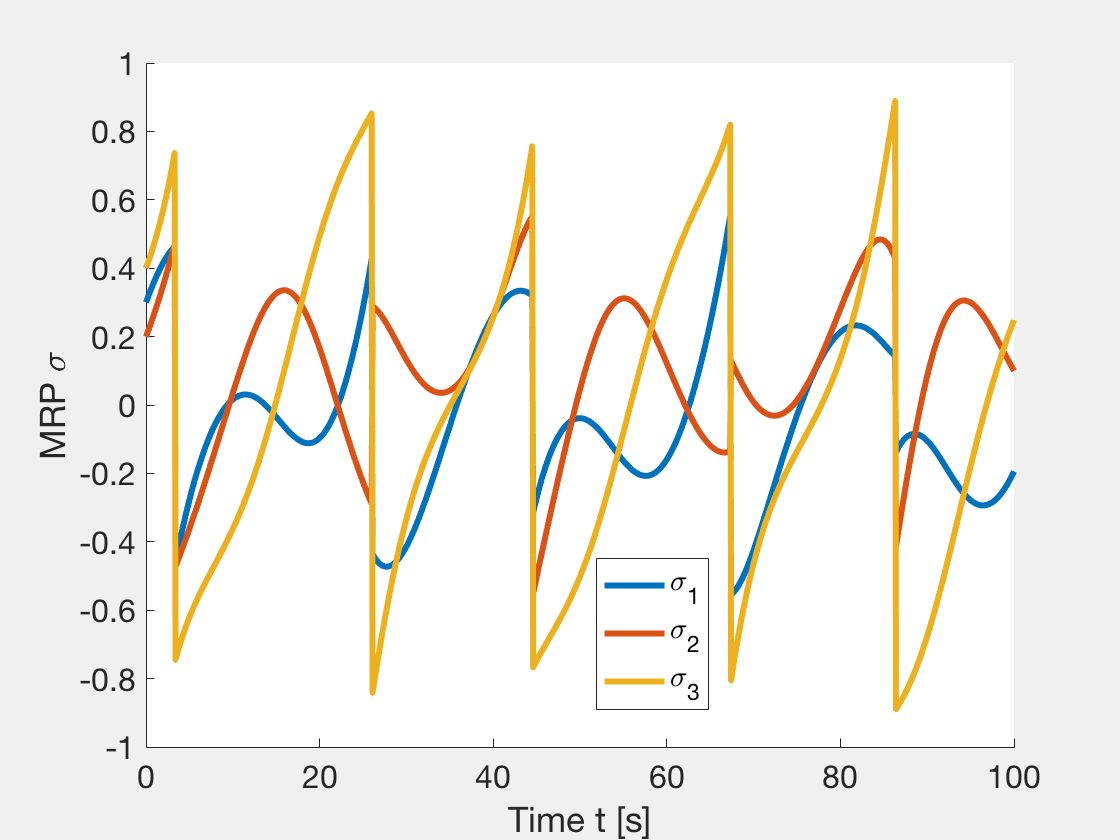

% This function can be found at the very bottom of this file.

% Integrate the state with my integrator for 100 seconds
sigma0 = [0.3, 0.2, 0.4]';
omega0 = deg2rad([15, 8, 12]'); % [rad/s]
x0 = [sigma0;omega0];
u = 'none';
global I;
I = diag([3.5, 5, 8]); % [kg-m^2]
tspan = 0:0.1:100; % [s]

[state, ~, ~] = intmrprk4(tspan, I, x0, u, 0);
sigma = state(1:3, :);
omega = state(4:6, :);

f1 = figure(1);
set(f1, 'defaultaxesfontsize', 16)
set(f1, 'Visible', 'on')
xlabel('Time t [s]')
ylabel('MRP \sigma')
hold on
plot(tspan, sigma(1, :), 'Linewidth', 3)
plot(tspan, sigma(2, :), 'Linewidth', 3)
plot(tspan, sigma(3, :), 'Linewidth', 3)
leg = legend('\sigma_1', '\sigma_2', '\sigma_3');
set(leg, 'Location', 'best')
hold off

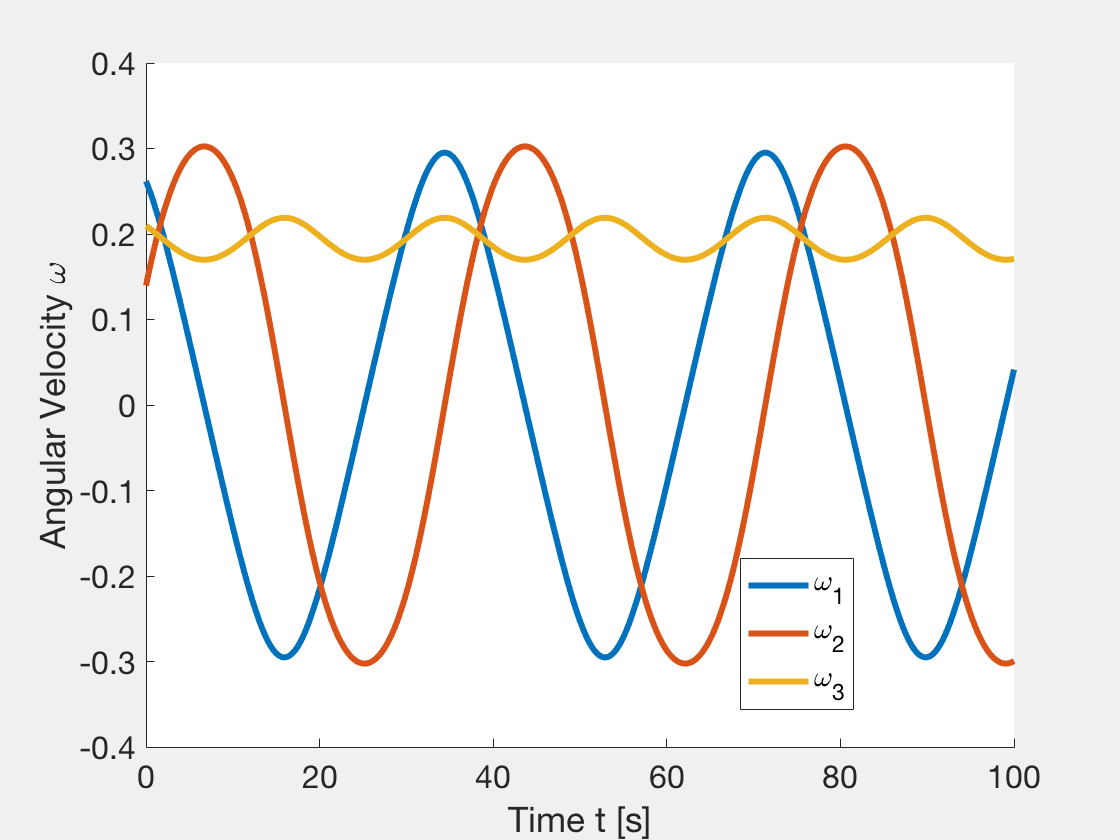


f2 = figure(2);
set(f2, 'defaultaxesfontsize', 16)
set(f2, 'Visible', 'on')
xlabel('Time t [s]')
ylabel('Angular Velocity \omega')
hold on
plot(tspan, omega(1, :), 'Linewidth', 3)
plot(tspan, omega(2, :), 'Linewidth', 3)
plot(tspan, omega(3, :), 'Linewidth', 3)
leg = legend('\omega_1', '\omega_2', '\omega_3');
set(leg, 'Location', 'best')
hold off

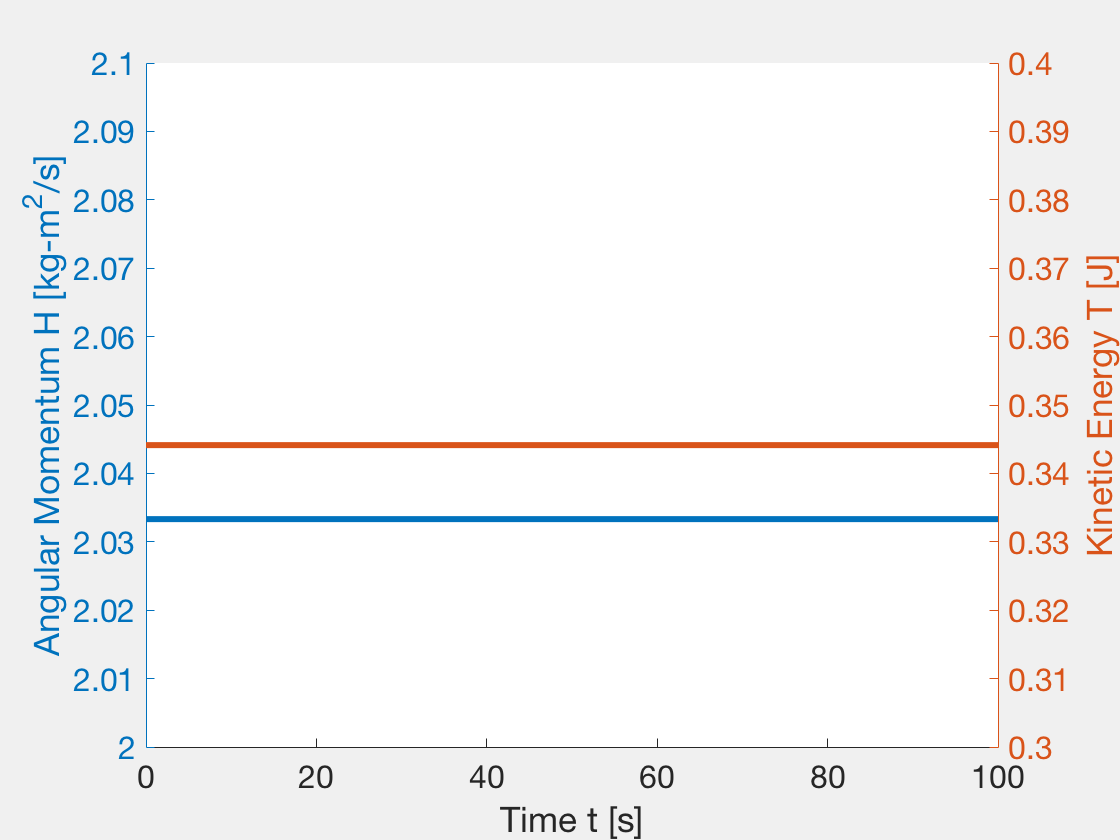

% Plot Angular Momentum and Kinetic Energy (should be conserved)

H = zeros(1, length(tspan));
KE = H;
for i = 1:length(tspan)
    Iomeg = I*omega(:, i);
    H(i) = norm(Iomeg);
    KE(i) = 1/2*norm(dot(Iomeg, omega(:, i)));
end

f3 = figure(3);
set(f3, 'defaultaxesfontsize', 16)
set(f3, 'Visible', 'on')
xlabel('Time t [s]')
ylabel('Angular Momentum H [kg-m^2/s]')
hold on
yyaxis left
plot(tspan, H, 'Linewidth', 3)
ylim([2.0 2.1])
yyaxis right
plot(tspan, KE, 'Linewidth', 3)
ylabel('Kinetic Energy T [J]')
ylim([0.3 0.4])
hold off

The angular momentum magnitude and kinetic energy are indeed constant.

# Milestone 3: Geomagnetic Modeling

## Modeling the tilted magnetic dipole using the coordinate frame representations

global beta_m_0; 
global M;
global gamma_m;
global omega_e;
beta_m_0 = 0; % [rad]
M = 7.838e6; % [T-km^3] dipole moment
gamma_m = deg2rad(17); % [rad] tilt angle
omega_e = 7.2921159e-5; % [rad/s] earth rotation rate about n3

% Orbital parameters
global R_Earth;
global h;
global r;
global mu;
R_Earth= 6378; % [km] Mean earth radius
h = 450; % [km] altitude
r = (h + R_Earth); % [m] orbital radius
mu = 398600; % [km^2/s^2] gravitational parameter

% LVLH reference frame angles
global Omega;
global theta0;
global thetadot;
global T;
global inc;
Omega = 0; % [rad] right ascension of the ascending node
inc = deg2rad(45); % [rad] inclination
theta0 = 0; % [rad] true anomaly (as argument of periapsis is not defined)
thetadot = sqrt(mu/r^3); % [rad/s] change in true anomaly
T = 2*pi*sqrt(r^3/mu); % [s] orbital period

## Plot the magnetic field $^H\bf b$ as seen by the orbit frame H over one orbit

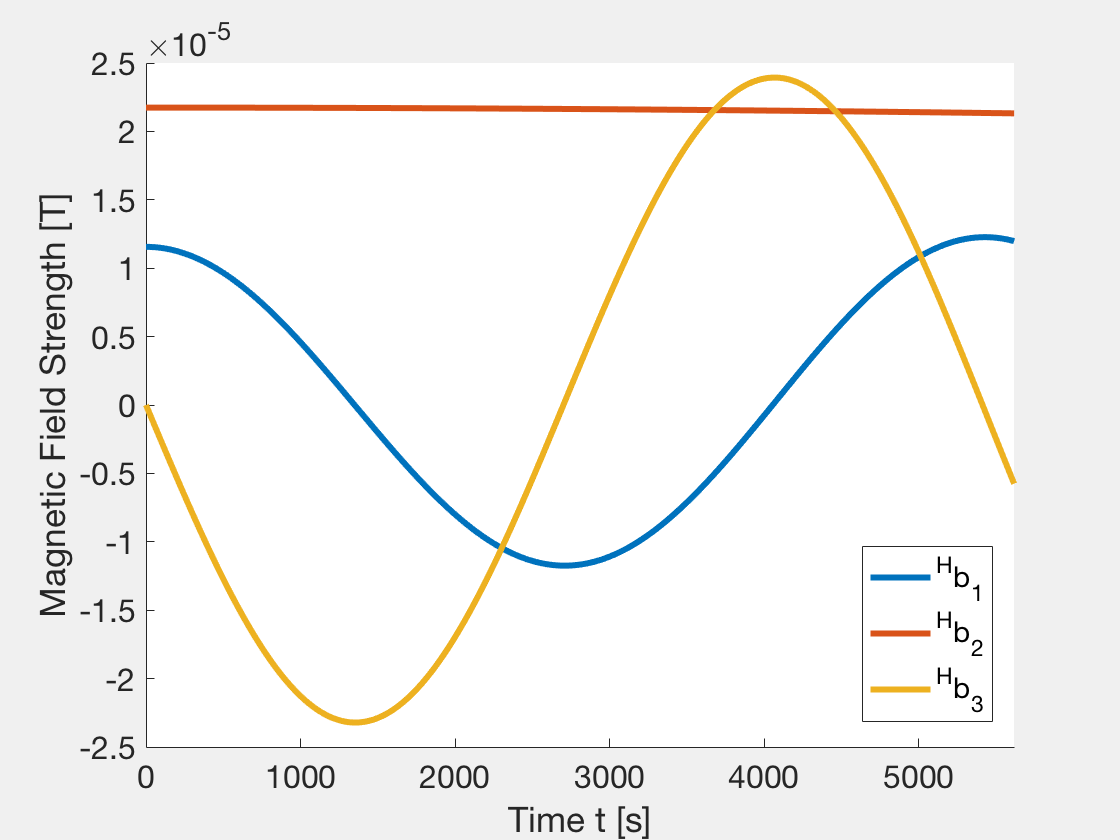

% No rk4 needed - no differential equation - simply nee a loop
tspan = 0:0.1:3*T; % [s] time propagation vector - 3 orbits to allow adequate time for detumbling
t = tspan(1);
h = tspan(2) - tspan(1); % [s] difference in time steps
% Propagate the state
ind = 1;
while (t <= tspan(end) + h)
    % Changing params
    beta_m = beta_m_0 + omega_e*t;
    xci_m = acos(cos(inc)*cos(gamma_m) + sin(inc)*sin(gamma_m)*cos(Omega - beta_m));
    eta_m = asin(sin(gamma_m)*sin(Omega - beta_m)/sin(xci_m));
    
    % Magnetic field
    Hb(:, ind) = M/r^3*[cos(thetadot*t - eta_m)*sin(xci_m);
                        cos(xci_m);
                        -2*sin(thetadot*t - eta_m)*sin(xci_m)];
                    
ind = ind + 1;
t = t + h;
end

f4 = figure(4);
set(f4, 'Visible', 'on')
set(f4, 'defaultaxesfontsize', 16)
hold on
xlabel('Time t [s]')
xlim([0 T])
ylabel('Magnetic Field Strength [T]')
plot(tspan, Hb(1, :), 'Linewidth', 3)
plot(tspan, Hb(2, :), 'Linewidth', 3)
plot(tspan, Hb(3, :), 'Linewidth', 3)
leg = legend('^Hb_1', '^Hb_2', '^Hb_3');
set(leg, 'Location', 'best')

## Plot the Magnetic Field as seen by the body frame for 100 seconds

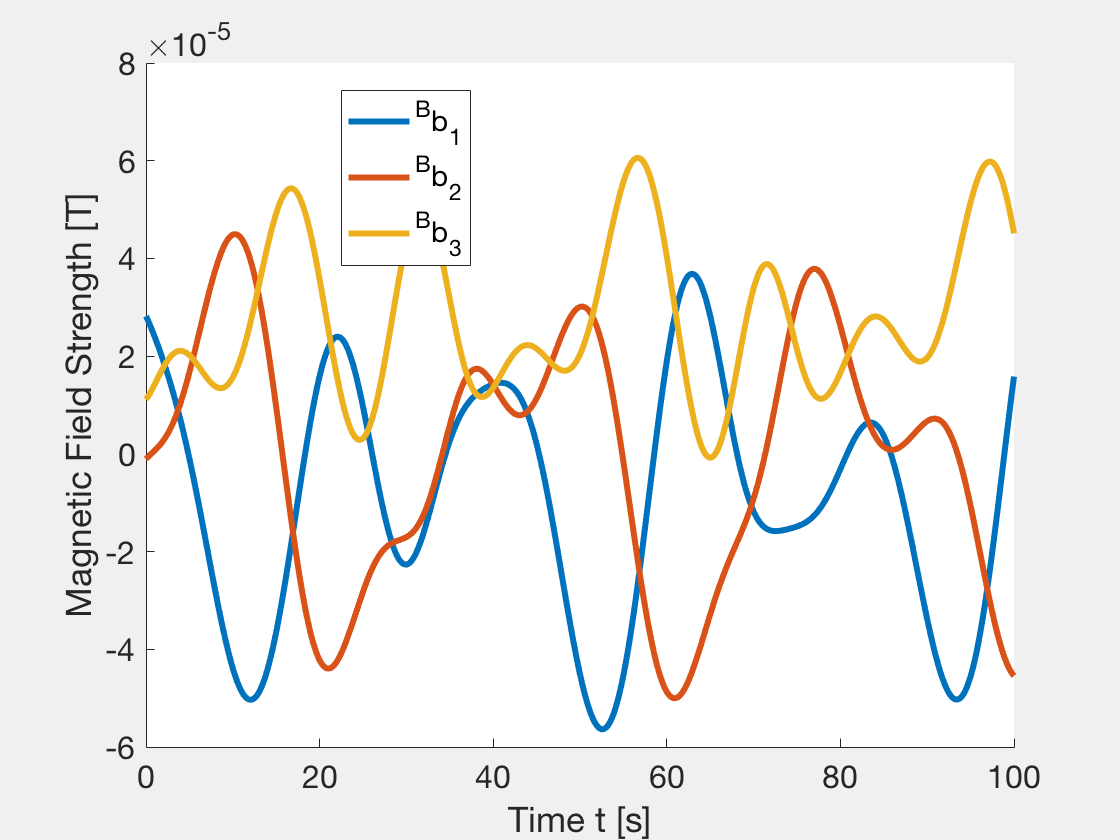

% Just need to convert H coordinates to B coordinates
% Bb = [BN][HN]'*Hb
tspan = 0:0.1:100;
h = tspan(2) - tspan(1);
t = tspan(1);
ind = 1;
while (t <= tspan(end))
    % [BN] DCM using MRPs calculated in Milestone 2
    s = sigma(:, ind);
    sq = s'*s;
    BN = eye(3) + (tilde(s)*(8*tilde(s) - 4*(1-sq)))/(1+sq)^2;
                 
    % [HN] DCM
    theta = theta0 + thetadot*t;
    HN = [cos(Omega)*cos(theta) - sin(Omega)*cos(inc)*sin(theta), sin(Omega)*cos(theta) + cos(Omega)*cos(inc)*sin(theta), sin(inc)*sin(theta);
          -cos(Omega)*sin(theta) - sin(Omega)*cos(inc)*cos(theta), cos(Omega)*cos(inc)*cos(theta) - sin(Omega)*sin(theta), cos(theta)*sin(inc);
          sin(Omega)*sin(inc), -cos(Omega)*sin(inc), cos(inc)];
      
    % [BH] DCM
    BH = BN*HN';
    Bb(:, ind) = BH*Hb(:, ind);
    
t = t + h;
ind = ind + 1;
end

% Plot it
f5 = figure(5);
set(f5, 'Visible', 'on')
set(f5, 'defaultaxesfontsize', 16)
hold on
xlabel('Time t [s]')
ylabel('Magnetic Field Strength [T]')
plot(tspan, Bb(1, :), 'Linewidth', 3)
plot(tspan, Bb(2, :), 'Linewidth', 3)
plot(tspan, Bb(3, :), 'Linewidth', 3)
leg = legend('^Bb_1', '^Bb_2', '^Bb_3');
set(leg, 'Location', 'best')

# Milestone 4: Control Law Implementation

## Implement the two B-dot control laws and integrate the model

Detumbling needs to occur within 3 orbits.

Use the following initial condtions for each control law

- $\sigma = (0.3, 0.2, 0.4)^T, \; \omega= (15, 8, 12)^T $ deg/s

- $\sigma = (0.1, 0.1, 0.4)^T, \; \omega= (1, 12, 1)^T $ deg/s

- $\sigma = (0.35, 0.2, 0.15)^T, \; \omega= (6, 4, 13)^T $ deg/s

Plot the magnetic dipole ***m*** for one of the initial conditions

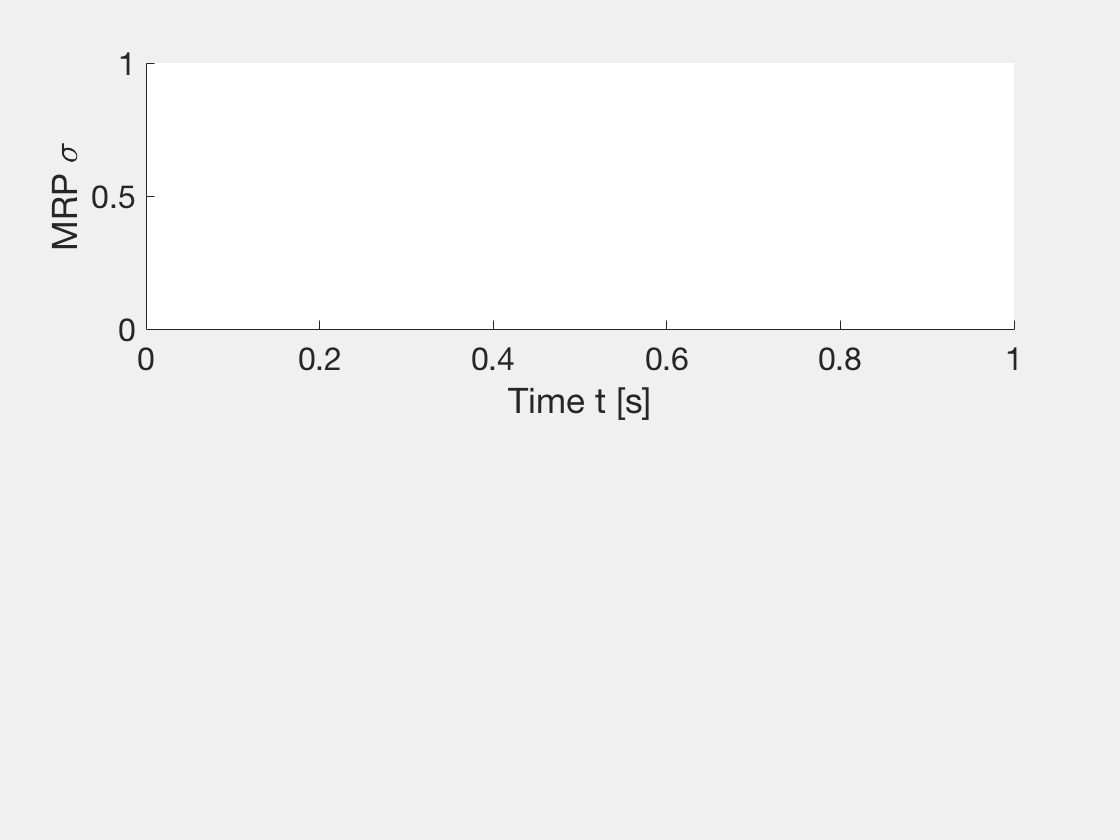

% Case 1 - Init Condit 1 and Modulating b-dot control law
sigma0 = [0.3, 0.2, 0.4]'; % [none]
omega0 = deg2rad([15, 8, 12]'); % [rad/s]
x0 = [sigma0;omega0];
tspan = 0:0.1:T;
control = 'mod';
[Xcase1, uCase1, mCase1] = intmrprk4(tspan, I, x0, control, Hb);
sigmaCase1 = Xcase1(1:3, :);
omegaCase1 = Xcase1(4:6, :);

% find where angular velocity meets 3 deg/s threshold
threshCase1 = findThresh(Xcase1(4:6, :));

f6 = figure(6);
set(f6, 'Visible', 'on')
set(f6, 'defaultaxesfontsize', 16)

subplot(2,1,1)
xlabel('Time t [s]')
ylabel('MRP \sigma')
hold on

plot(tspan, sigmaCase1(1, :), 'Linewidth', 3)

Error using plot
Vectors must be the same length.

plot(tspan, sigmaCase1(2, :), 'Linewidth', 3)
plot(tspan, sigmaCase1(3, :), 'Linewidth', 3)
leg = legend('\sigma_1', '\sigma_2', '\sigma_3');
set(leg, 'Location', 'best')

subplot(2,1,2)
xlabel('Time t [s]')
ylabel('Angular Velocity \omega [rad/s]')
hold on
plot(tspan, omegaCase1(1, :), 'Linewidth', 3)
plot(tspan, omegaCase1(2, :), 'Linewidth', 3)
plot(tspan, omegaCase1(3, :), 'Linewidth', 3)
leg = legend('\omega_1', '\omega_2', '\omega_3');
set(leg, 'Location', 'best')
f7 = figure(7);
set(f7, 'Visible', 'on')
set(f7, 'defaultaxesfontsize', 16)

subplot(2,1,1)
xlabel('Time t [s]')
ylabel('MRP \sigma')
hold on
plot(tspan, uCase1(1, :), 'Linewidth', 3)
plot(tspan, uCase1(2, :), 'Linewidth', 3)
plot(tspan, uCase1(3, :), 'Linewidth', 3)
leg = legend('u_1', 'u_2', 'u_3');
set(leg, 'Location', 'best')

subplot(2,1,2)
xlabel('Time t [s]')
ylabel('Angular Velocity \omega [rad/s]')
hold on
plot(tspan, mCase1(1, :), 'Linewidth', 3)
plot(tspan, mCase1(2, :), 'Linewidth', 3)
plot(tspan, mCase1(3, :), 'Linewidth', 3)
leg = legend('m_1', 'm_2', 'm_3');
set(leg, 'Location', 'best')

function [X, u, m] = intmrprk4(tspan, I, x0, control, Hb)
%INTMRPRK4 Numerically integrate the Modified Rodriguez Parameters and
%angular velocity vector using the rigid body equations of motion and the 
%RK4 numerical method. 
% 
% Purpose
%   To numerically integrate the state x = [sigma, omega]'
%
% Inputs
%   tspan - vector of time points, evenly spaced
%   I - inertia tensor of rigid body (aligned with princip. axis frame)
%   x0 - initial state, [sigma0, omega0] (must be a column vector)
%   u - control law
% Outputs
%   X - matrix of states propagated with t
%
% Author(s):
%   Ian Coooke
%
% Created
%   8 Apr 2018
% Modified
%   23 Apr 2018
% Log
%   8 Apr 2018
%   23 Apr 2018
%       Added control
%       
%-ASEN5010-ASEN5010-ASEN5010-ASEN5010-ASEN5010-ASEN5010-ASEN5010-ASEN5010-%

% Define global variables
global theta0;
global thetadot;
global Omega;
global inc;
global beta_m_0;
global omega_e;

% Extract the states
sigma0 = x0(1:3);
omega0 = x0(4:6);

% Integration setup
n = length(tspan);

sigma = zeros(3, n);
omega = sigma;

u = sigma;
m = sigma;

sigma(:, 1) = sigma0;
omega(:, 1) = omega0;

h = tspan(2) - tspan(1);
t = tspan(1);

% Integration loop
ind = 1;
while (t <= tspan(end))
    
    % current states
    s = sigma(:, ind);
    w = omega(:, ind);
    
    % MRPs
    % k1
    sq = s'*s; %sigma^2
    Q = tilde(s); % tilde(sigma)
    B = (1 - sq)*eye(3) + 2*Q + 2*s*s'; % B-matrix
    k1 = 1/4*B*w;
    
    % k2
    s2 = s + h*k1/2;
    sq = s2'*s2;
    Q = tilde(s2);
    B = (1- sq)*eye(3) + 2*Q + 2*s2*s2';
    k2 = 1/4*B*w;
    
    % k3
    s3 = s + h*k2/2;
    sq = s3'*s3;
    Q = tilde(s3);
    B = (1- sq)*eye(3) + 2*Q + 2*s3*s3';
    k3 = 1/4*B*w;
    
    % k4
    s4 = s + h*k3;
    sq = s4'*s4;
    Q = tilde(s4);
    B = (1- sq)*eye(3) + 2*Q + 2*s4*s4';
    k4 = 1/4*B*w;
    
    % next state
    sigma(:, ind+1) = sigma(:, ind) + h/6*(k1 + 2*k2 + 2*k3 + k4);
    
    % MRP switching
    if (norm(sigma(:, ind+1)) > 1)
        sigma(:, ind+1) = -sigma(:, ind+1)/norm(sigma(:, ind+1))^2;
    end
    
    % control law
    % only calculate magnetic field if you're using control
    if strcmp(control, 'mod') || strcmp(control, 'bang')
         s = sigma(:, ind);
        % Magnetic field in B components (H components already calculated)
        BN = eye(3) + (tilde(s)*(8*tilde(s) - 4*(1-s'*s)))/(1+s'*s)^2;
                     
        % [HN] DCM
        theta = theta0 + thetadot*t;
        beta_m = beta_m_0 + omega_e*t;
        HN = [cos(Omega)*cos(theta) - sin(Omega)*cos(inc)*sin(theta), sin(Omega)*cos(theta) + cos(Omega)*cos(inc)*sin(theta), sin(inc)*sin(theta);
              -cos(Omega)*sin(theta) - sin(Omega)*cos(inc)*cos(theta), cos(Omega)*cos(inc)*cos(theta) - sin(Omega)*sin(theta), cos(theta)*sin(inc);
              sin(Omega)*sin(inc), -cos(Omega)*sin(inc), cos(inc)];
          
        % [BH] DCM
        BH = BN*HN';
        Bb = BH*Hb(:, ind);
        % modulating b-dot control law
        if strcmp(control, 'mod')
            m(:, ind) = modControl(Bb, beta_m, omega(:, ind));
        % bang-bang b-dot control law
        elseif strcmp(control, 'bang')
            % Numerical differentiate
            bp = diff(Bb(:, ind+1),Bb(:,ind));
            m(:, ind) = bangControl(bp);
        end
    elseif strcmp(control, 'none')
        m(:, ind) = zeros(3,1);
        Bb = m(:, ind);
    else
        error('invali control law')
    end
    
    % Calculate control
    u(:, ind) = cross(m(:, ind), Bb); 
    
    % omega
    % k1
    k1 = I^-1*(-tilde(w)*I*w + u(:, ind));
    
    % k2
    w2 = w + h/2*k1;
    k2 = I^-1*(-tilde(w2)*I*w2 + u(:, ind));
    
    % k3
    w3 = w + h/2*k2;
    k3 = I^-1*(-tilde(w3)*I*w3 + u(:, ind));
    
    % k4
    w4 = w + h*k3;
    k4 = I^-1*(-tilde(w4)*I*w4 + u(:, ind));
    
    % next state
    omega(:, ind+1) = omega(:, ind) + h/6*(k1 + 2*k2 + 2*k3 + k4);
    
ind=ind+1;
t = t + h;
end

X = [sigma; omega];
X = X(:, 1:end-1);

end

function [m] = modControl(Bb, beta_m, omega)
%MODCONTROL Numerically calculate the magnetic dipole to command the control torque
% 
% Purpose
%   To numerically calculate the magnetic dipole moment
%
% Inputs
%   Bb - Magnetic field at instant in time as seen by satellite frame
%   beta_m - angle between magnetic frame and inertial frame
%   omega - current angular velocity vector as seen by inertial frame
% Outputs
%   m - magnetic dipole
%
% Author(s):
%   Ian Coooke
%
% Created
%   23 Apr 2018
% Modified
%   23 Apr 2018
% Log
%   23 Apr 2018
%       
%-ASEN5010-ASEN5010-ASEN5010-ASEN5010-ASEN5010-ASEN5010-ASEN5010-ASEN5010-%
    % Global variables
    global I;
    global thetadot;
    global inc;
    global gamma_m;
    global Omega;
    
    m_max = 3;
    
    bhat = Bb./norm(Bb);
    
    xi_m = acos(cos(inc)*cos(gamma_m) + sin(inc)*sin(gamma_m)*cos(Omega - beta_m));
    k_w = 2*thetadot*(1+sin(xi_m))*min(diag(I));
    m = cross(-k_w/norm(Bb)*bhat, (eye(3) - Bb*Bb')*omega);
    
    % Enforce dipole saturation
    for j = 1:3
        if abs(m(j)) > m_max
            m(j) = m_max;
        end
    end
end

function [m] = bangControl(bp)
     m_max = 3;
     m = -m_max*sign(bp);
end

function [res] = findThresh(omega)
    thresh = deg2rad(3);
    res = zeros(3,1);
    for j = 1:length(omega)
        if omega(1,j) < thresh
            res(1) = j;
        elseif omega(2,j) < thresh
            res(2) = j;
        elseif omega(3,j) < thresh
            res(3) = j;
        end
        res = max(res);
    end
end